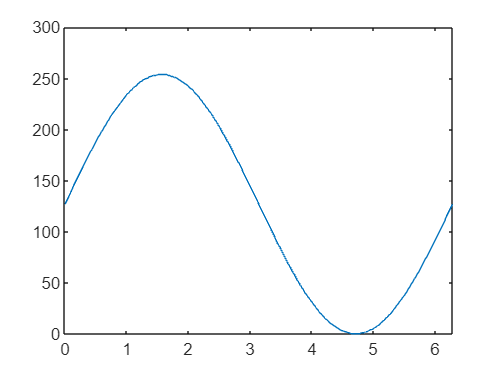

x = linspace(0, 2*pi, 256);
y = round((sin(x) + 1) * 127, 0);
plot(x,y)

saveSinMif(y);

function saveSinMif(arr)
    fid = fopen('sinRom.mif','w');
    fprintf(fid,'WIDTH=8;\n');
    fprintf(fid,'DEPTH=256;\n');
    fprintf(fid,'ADDRESS_RADIX=UNS;\n');
    fprintf(fid,'DATA_RADIX=DEC;\n');
    fprintf(fid,'CONTENT BEGIN\n');
    
    for k = 1:256
      fprintf(fid, '%i : %i;\n', k - 1, arr(k));
    end
    
    fprintf(fid,'END;');
    fclose(fid);
end